img=imread("图片/2.jpg");
img=im2double(img);


## 灰度化与高斯滤波

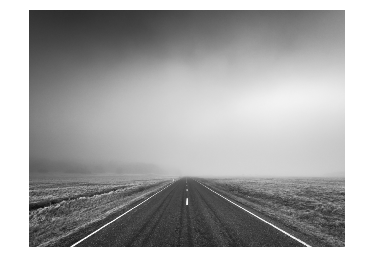

%imshow(img);
img_g=rgb2gray(img);


W=fspecial("gaussian",[5,5],1);
img_new=imfilter(img_g,W,"replicate");
imshow(img_new);

使用sobel算子计算梯度

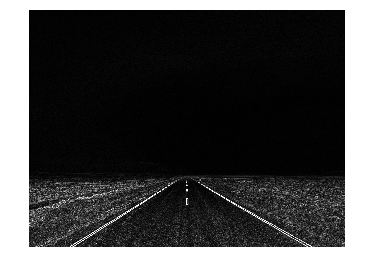

[rows,cols] = size(img_new);
mask_X = [-1 -2 -1;...  %定义梯度矩阵
           0  0  0;...
           1  2  1];
mask_Y = [-1 0 1;...
          -2 0 2;...
          -1 0 1;];
dstImg=img_new;
gradx=zeros(rows,cols);
grady=zeros(rows,cols);
for i = 1:rows-2
    for j = 1:cols-2
        tempx = mask_X.*img_new(i:i+2,j:j+2);
        tempy = mask_Y.*img_new(i:i+2,j:j+2);
        temp_X = sum(tempx(:));
        temp_Y = sum(tempy(:));
        %dstImg(i+1,j+1) = abs(temp_X)+abs(temp_Y);
        dstImg(i+1,j+1)=sqrt((temp_X^2)+(temp_Y^2));
        gradx(i,j)=temp_X;
        grady(i,j)=temp_Y;
    end
end
dstImg_show=im2uint8(dstImg);
imshow(dstImg_show);

## 非最大值抑制

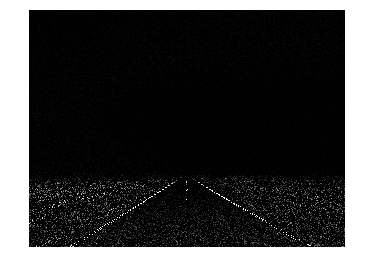


output=NMS_algo(dstImg,gradx,grady);
imshow(output)

## 阈值处理

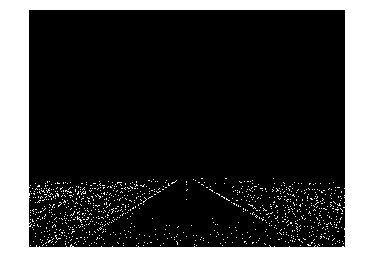

jd=double(output);
st = zeros(rows,cols);%定义一个双阈值图像
TL = 0.1 * max(max(jd));%低阈值
TH = 0.3* max(max(jd));%高阈值
for i = 1  : rows
    for j = 1 : cols
        if (jd(i, j) < TL)
            st(i,j) = 0;
        elseif (jd(i, j) > TH)
            st(i,j) = 1 ;
        %对TL < Nms(i, j) < TH 使用8连通区域确定
        elseif (jd(i, j)<TH&&jd(i, j)>TL)
            su =[jd(i-1,j-1), jd(i-1,j), jd(i-1,j+1);
                       jd(i,j-1),    jd(i,j),   jd(i,j+1);
                       jd(i+1,j-1), jd(i+1,j), jd(i+1,j+1)];
            Max = max(su);
            if Max>=TH
                st(i,j) = 1 ;
            end

        end
    end
end
imshow(st);

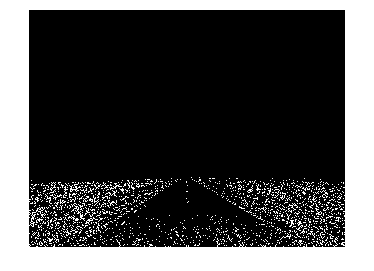

Bw=edge(st,'canny');
imshow(Bw)

function output = NMS_algo(grad,gradx,grady)
% 非极大值抑制函数
grad = double(grad);
[h,w] = size(grad);
% 初始化结果
result = zeros(h,w);
% 抑制算法实现
% 用线性插值算出梯度方向上亚像素点的梯度值
% 权重初始化
weight = zeros(h,w);
% 各像素点梯度值初始化
grad1 = zeros(h,w);
grad2 = zeros(h,w);
grad3 = zeros(h,w);
grad4 = zeros(h,w);
gradTemp1 = zeros(h,w);
gradTemp2 = zeros(h,w);
for i = 2:(h-1)
    for j = 2:(w-1)
        % 梯度为0的点直接在结果中置0
        if grad(i,j) == 0
            result(i,j) = 0;
        % 对于梯度不为0的点
        else
            % y方向梯度大于x方向梯度
            if abs(grady(i,j)) > abs(gradx(i,j))
                % 计算权重
                weight(i,j) = abs(gradx(i,j))/abs(grady(i,j));
                % 中心点上下两点
                grad2(i,j) = grad(i-1,j);
                grad4(i,j) = grad(i+1,j);
                % gradx和grady同号
                if gradx(i,j) * grady(i,j) > 0
                    % 插值用到的另外两点
                    grad1(i,j) = grad(i-1,j-1);
                    grad3(i,j) = grad(i+1,j+1);
                % gradx和grady异号
                else
                    grad1(i,j) = grad(i-1,j+1);
                    grad3(i,j) = grad(i+1,j-1);
                end
            % y方向梯度小于x方向梯度
            else
                weight(i,j) = abs(grady(i,j))/abs(gradx(i,j));
                grad2(i,j) = grad(i,j-1);
                grad4(i,j) = grad(i,j+1);
                % gradx和grady同号
                if gradx(i,j) * grady(i,j) > 0
                    grad1(i,j) = grad(i+1,j-1);
                    grad3(i,j) = grad(i-1,j+1);
                % gradx和grady异号    
                else
                    grad1(i,j) = grad(i-1,j-1);
                    grad3(i,j) = grad(i+1,j+1);
                end
            end
        end
        % 插值计算计算两个亚像素点梯度值
        gradTemp1(i,j) = weight(i,j) * grad1(i,j) + (1 - weight(i,j)) * grad2(i,j);
        gradTemp2(i,j) = weight(i,j) * grad3(i,j) + (1 - weight(i,j)) * grad4(i,j);
        % 比较中心像素点和两个亚像素点的梯度值
        if (grad(i,j) >= gradTemp1(i,j) && grad(i,j) >= gradTemp2(i,j))
            % 中心点在其邻域内为极大值，在结果中保留其梯度值
            result(i,j) = grad(i,j);
        else
            % 否则的话，在结果中置0
            result(i,j) = 0;
        end     
    end
end
output = im2uint8(result);      %注意！
end
